# Energy Prices - Multivariate Statistics

Open and inspect the file `Fuels.xls` in Excel.  This file contains time and price information for three different fuels in the first sheet. 

## 1.

Import the data from the first sheet into a table.

fuelPrices = readtable('Fuels.xls')

fuelPrices = 2659×4 table
       Date       NaturalGas    CrudeOil    FuelOil
    __________    __________    ________    _______
    31.12.1999      2.305         25.6      0.7055 
    03.01.2000      2.305         25.6      0.7055 
    04.01.2000       2.14        25.55      0.6738 
    05.01.2000      2.165        24.93      0.6595 
    06.01.2000      2.185        24.78      0.6776 
    07.01.2000      2.195        24.23      0.6613 
    10.01.2000        2.2        24.68        0.66 
    11.01.2000      2.235        25.78      0.6778 
    12.01.2000      2.245        26.28      0.6937 
    13.01.2000      2.285        26.68      0.7118 
    14.01.2000      2.285        28.03       0.733 
    17.01.2000      2.285        28.03       0.733 
    18.01.2000       2.34        28.85      0.8192 
    19.01.2000       2.34        29.53      0.8716 
    20

## 2.

Convert variables 2 to 4 of the table into a double matrix and apply the transformation: 

`zscore``(diff(log(X)))`.

**Note** This transformation calculates normalized log returns from the fuel prices.

fuelReturns = zscore(diff(log( fuelPrices{:,2:end} )))

fuelReturns =    -0.0053   -0.0167   -0.0141
   -1.6098   -0.0910   -1.5921
    0.2456   -0.9510   -0.7504
    0.1933   -0.2462    0.9152
    0.0933   -0.8703   -0.8499
    0.0438    0.6832   -0.0817
    0.3357    1.6418    0.8993
    0.0911    0.7139    0.7817
    0.3762    0.5579    0.8699
   -0.0053    1.8607    0.9932


## 3.

Perform a principal component analysis (PCA) on the fuel returns and ask for at least two outputs.

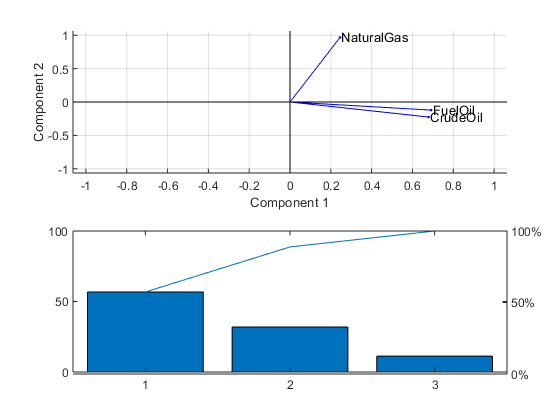

[coeff,loads,~,~,variance] = pca(fuelReturns);

% OPTIONAL: Visualize the results
figure
subplot(2,1,1)
biplot(coeff(:,1:2), 'VarLabels', fuelPrices.Properties.VariableNames(2:end))
subplot(2,1,2)
pareto(variance)

## 4.

Approximate all fuel return series by fitting only the first and second principal components. **Hint** No regression necessary; multiply the PCA scores with the PCA coefficients.

fittedReturns = loads(:,1:2) * coeff(:,1:2)'

fittedReturns =    -0.0052   -0.0153   -0.0155
   -1.6798   -0.7556   -0.9142
    0.2538   -0.8731   -0.8298
    0.2529    0.3189    0.3388
    0.0930   -0.8734   -0.8467
    0.0042    0.3073    0.3017
    0.2966    1.2714    1.2771
    0.0949    0.7499    0.7450
    0.3911    0.6991    0.7258
   -0.0488    1.4478    1.4144


## 5.

Visually compare the returns by plotting the original returns and the approximation (from step 4) on the same axis against the dates.

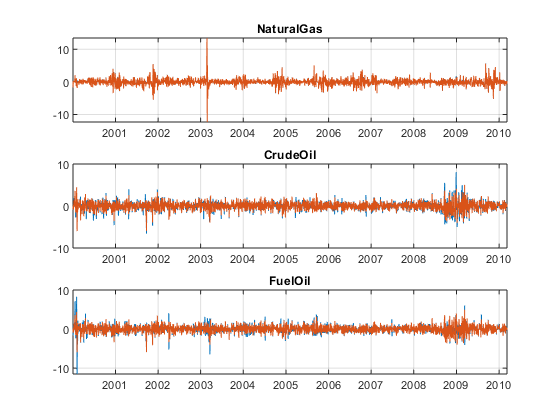

dates = datetime(fuelPrices.Date(2:end),'InputFormat','MM/dd/yyyy');
nFuels = size(fuelReturns,2);
figure
for fuelIdx = 1:nFuels
    subplot(nFuels,1,fuelIdx)
    plot(dates, [fuelReturns(:,fuelIdx), fittedReturns(:,fuelIdx)]);
    title(fuelPrices.Properties.VariableNames{1+fuelIdx})
    datetick
    xlim([min(dates),max(dates)])
    grid('on')
end